# Lab 1

Physics 434

Francesca Bennett

close all;
%Lab 1 Physics 434
%Oct 8, 2019

## Part 1

Showing that values of sigma align with expected probabilities.

**Part 1.B**

For various sigma values (sigma1, sigma2, sigma 3), the resulting probability is found for each respective value using the "normcdf" function. Each probability is listed at the end for convinience.

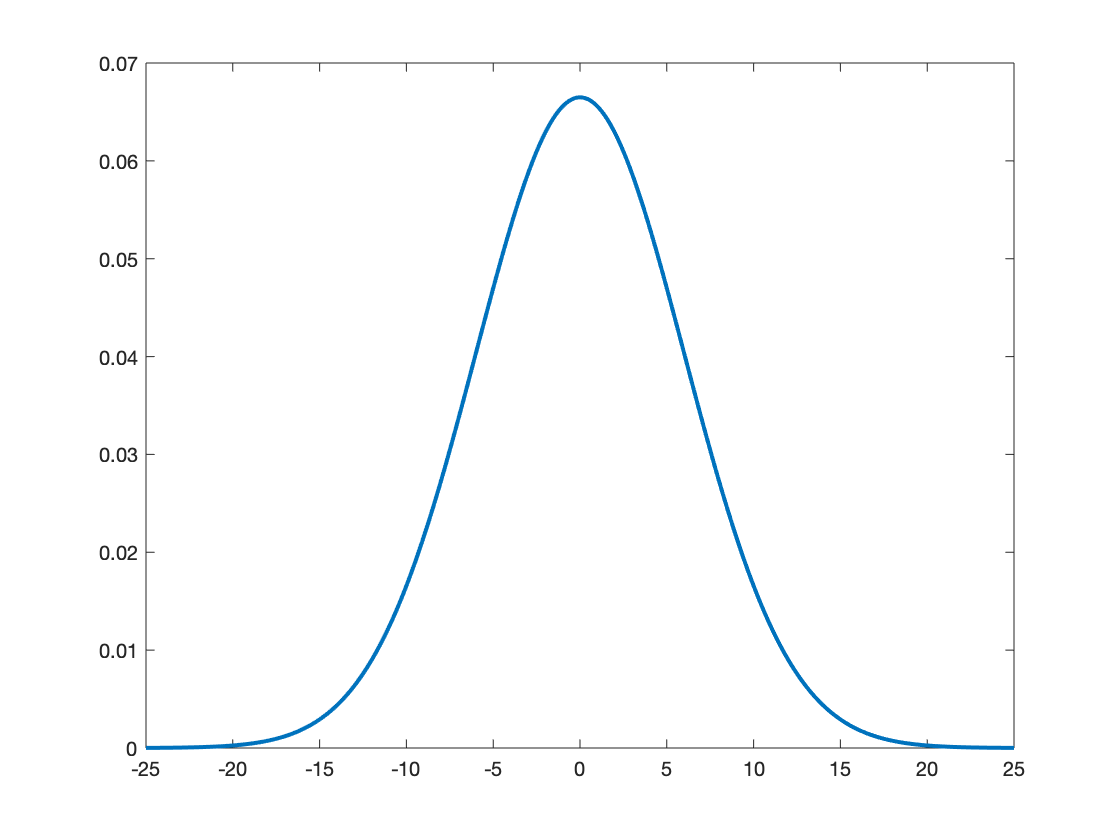

mu=0;
sigma1=6;
Dist1 = makedist('Normal', 'mu',mu,'sigma',sigma1);
x1=linspace(-25,25,1000);
plot(x1,pdf(Dist1,x1),"Linewidth",2);

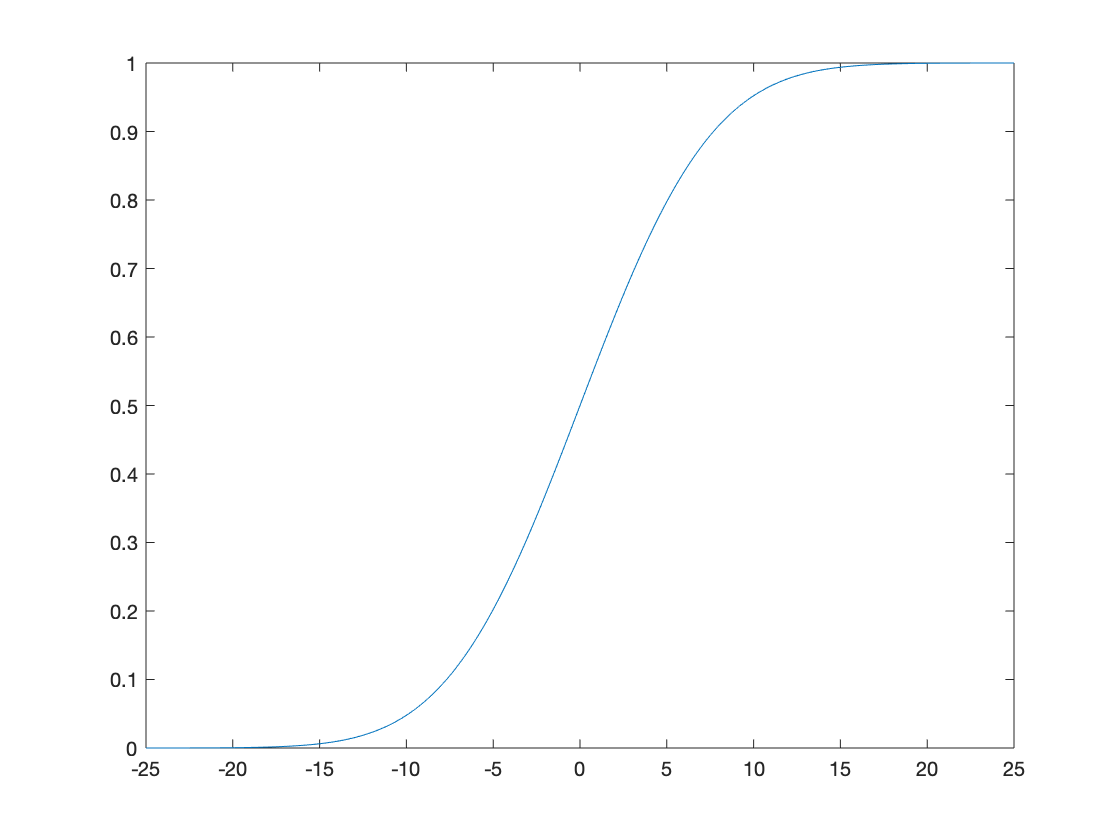

plot(x1,normcdf(x1,mu,sigma1));


%Integral of the normal distribution, giving a probability of something
Prob1=normcdf(1,mu,sigma1)

Prob1 = 0.5662

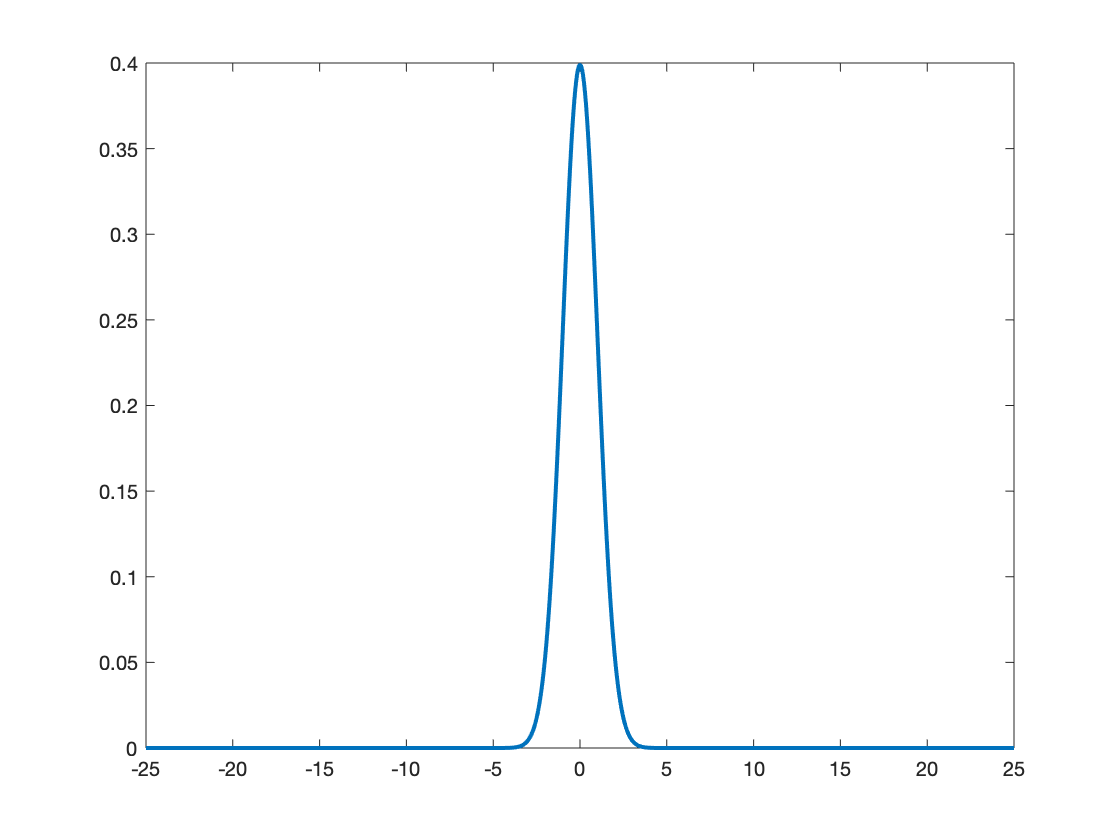


%Sigma2, Prob 2
mu=0;
sigma2=1;
Dist1 = makedist('Normal', 'mu',mu,'sigma',sigma2);
x1=linspace(-25,25,1000);
plot(x1,pdf(Dist1,x1),"Linewidth",2);

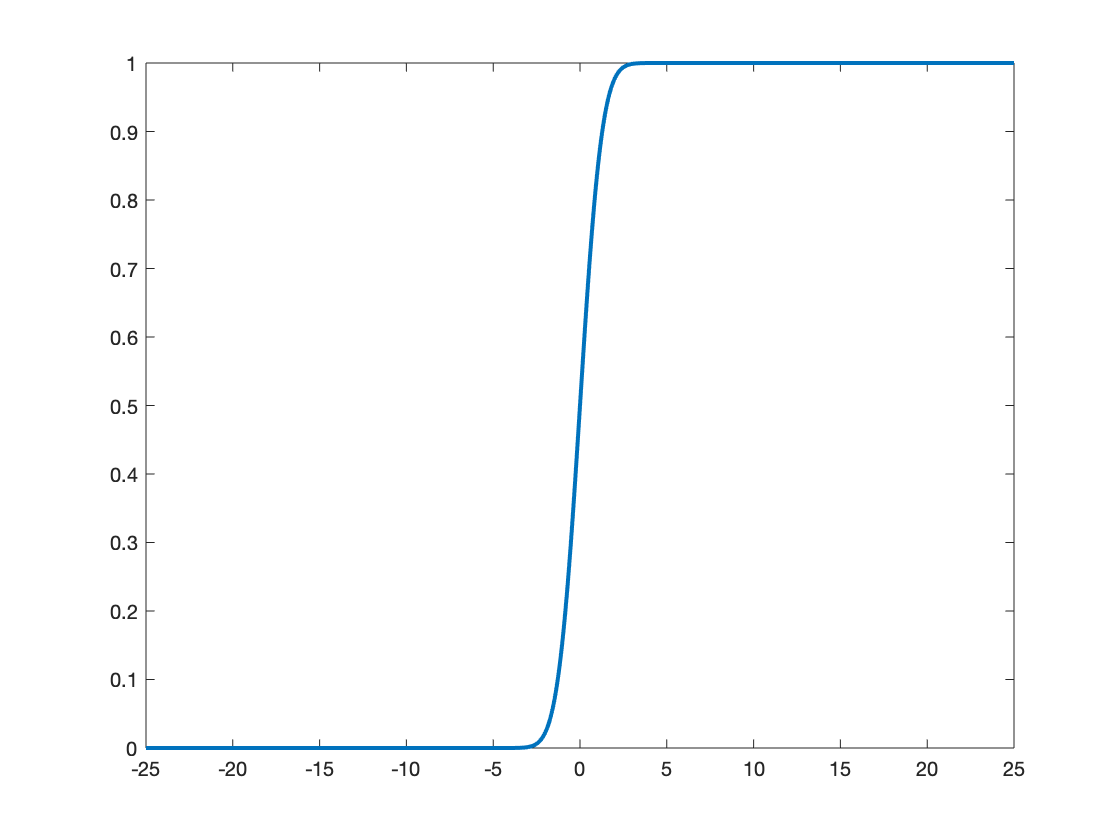

plot(x1,normcdf(x1,mu,sigma2),"Linewidth",2);


%Integral of the normal distribution, giving a probability of something
Prob2=normcdf(1,mu,sigma2)

Prob2 = 0.8413

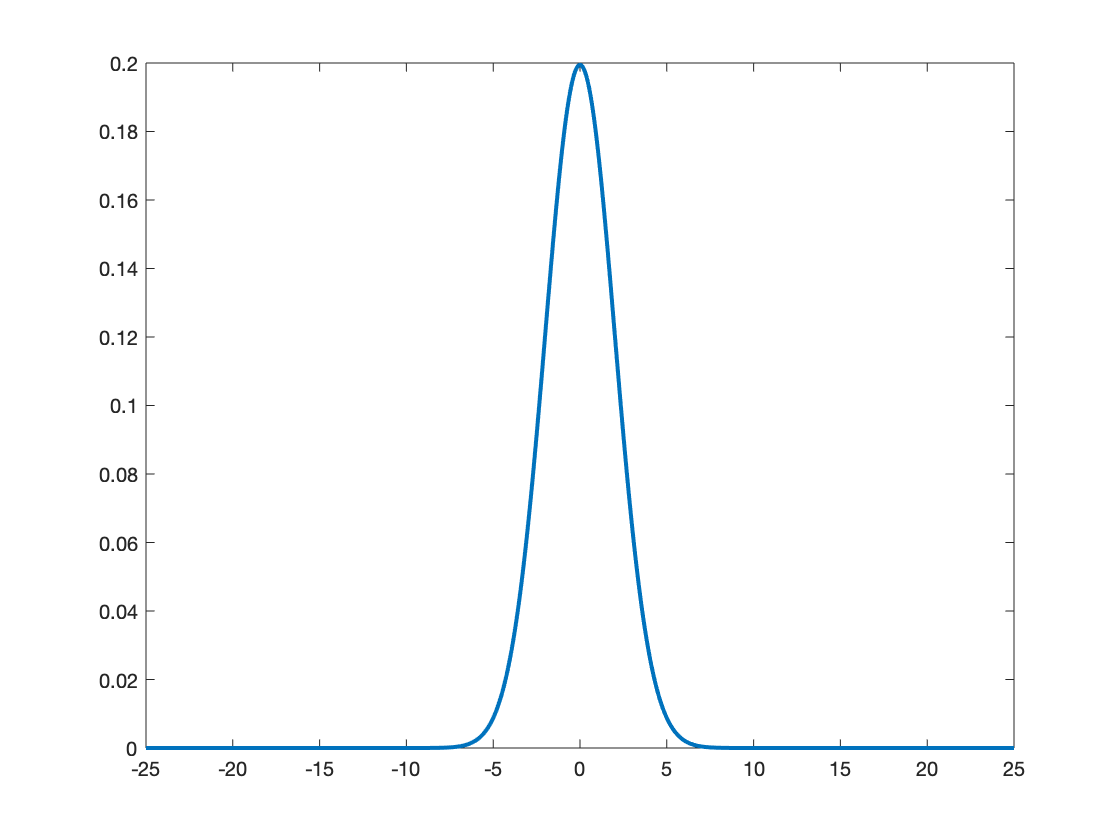


%Sigma3, Prob3
mu=0;
sigma3=2;
Dist1 = makedist('Normal', 'mu',mu,'sigma',sigma3);
x1=linspace(-25,25,1000);
plot(x1,pdf(Dist1,x1),"Linewidth",2);

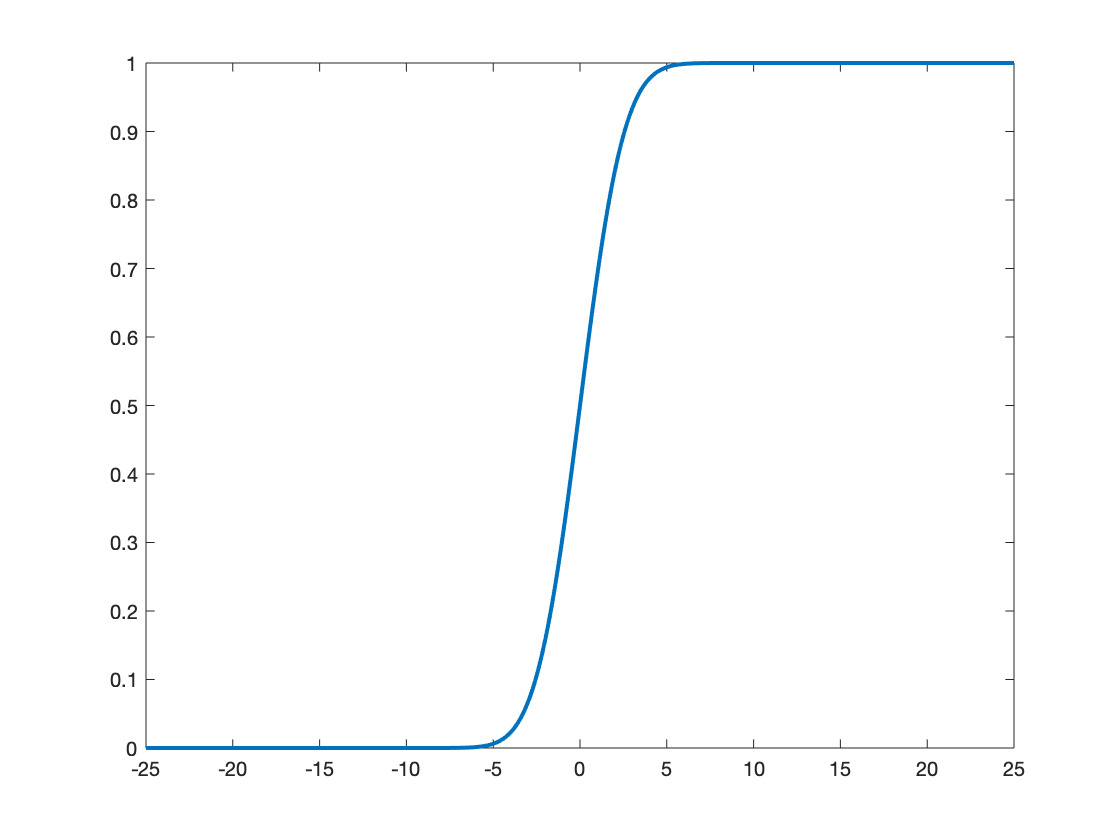

plot(x1,normcdf(x1,mu,sigma3),"LineWidth",2);


%Integral of the normal distribution, giving a probability of something
Prob1=normcdf(1,mu,sigma1)

Prob1 = 0.5662

Prob2=normcdf(1,mu,sigma2)

Prob2 = 0.8413

Prob3=normcdf(1,mu,sigma3)

Prob3 = 0.6915

**Part 1.C**

From Wikipedia's listed z-tables, it is known that 

Sigma=6 should have a probability of 

Sigma=1 should have a probability of 

Sigma=2 should have a probability of

Now, these known probabilities are put into "norminv" to check that their sigma values are what is expected.

%Part 1.B
Check1=norminv(0.5766,mu,6)

Check1 = 1.1592

Check2=norminv(0.8769,mu,1)

Check2 = 1.1596

Check3=norminv(0.7190,mu,2)

Check3 = 1.1597

**Part 1.D**

A negative sign is the result of integrating backwords, that is, integrating to the left. The result will be positive if integration is to the right of the graph.

### Problem 2: Rayleigh Distributions

**Part 2.A**

Rayleigh distributions are very similar to chi-squared distributions, except with two degrees of freedom. 

**Part 2.B**

Plot of Rayleigh

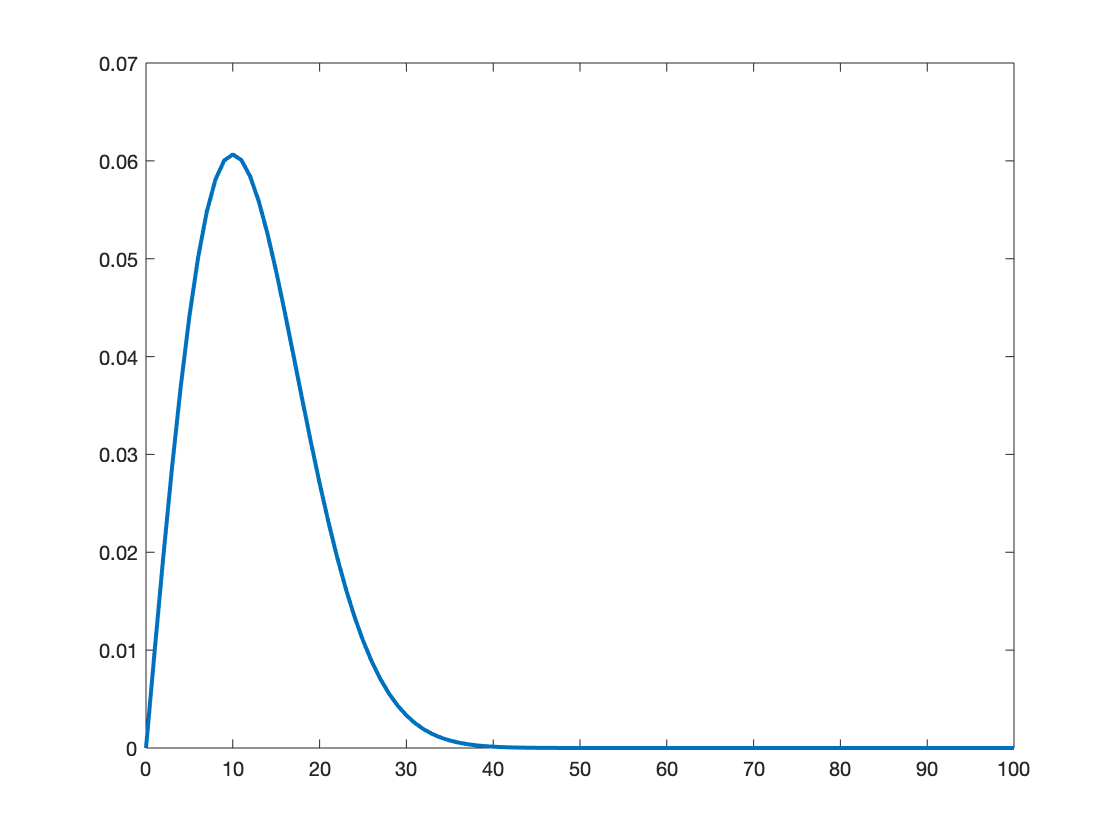

r = [0:100];
ray = raylpdf(r,10);
figure;
plot(r,ray, "Linewidth",2);

#### Problem 3: Signal Background

**Part 3.A**

Value of hypothetical measurement: r1=20

**Part 3.B**

Question: What is the probability that the chosen value, r1=20, is signal free?

**Part 3.C**

From the point r1=20, an integral is taken, using raylcdf, to find the probability.

r1 = 20;
Pr1 = raylcdf(r1,10,'upper')

Pr1 = 0.1353

**Part 3.D**

The calculated probability of getting a signal at r1=20 is recorded:

Pr1=0.1353

**Part 3.E**

Converting the calculated probability to a sigma value using "raylinv," it is found that,

r1sigma=raylinv(0.1353,10)

r1sigma = 5.3921

#### Problem 4

Various probabilities and sigmas are tested for the Rayleigh distribution, and it is show that the probability of getting a signal increases as we choose a smaller value of "r," respresented on the x-axis. 

r2 = 15;
Pr2 = raylcdf(r2,10,'upper')

Pr2 = 0.3247

r2sigma=raylinv(Pr2,10)

r2sigma = 8.8603


r3 = 10;
Pr3 = raylcdf(r3,10,'upper')

Pr3 = 0.6065

r3sigma=raylinv(Pr3,10)

r3sigma = 13.6583

### Part II: Non-Continuous Distributions

**Part A**

This sections looks at an examination of the Poisson distribution. Unlike the Rayleigh distribution, the Poisson distribution is a discrete, rather than continuous, probability function. It is for events that occur independently of the time since the most previous event, because it represents the chances that an event will occur for any specified time interval. 

**Part B**

Discrete plots of the Poisson distribution are shown, using various parameters.

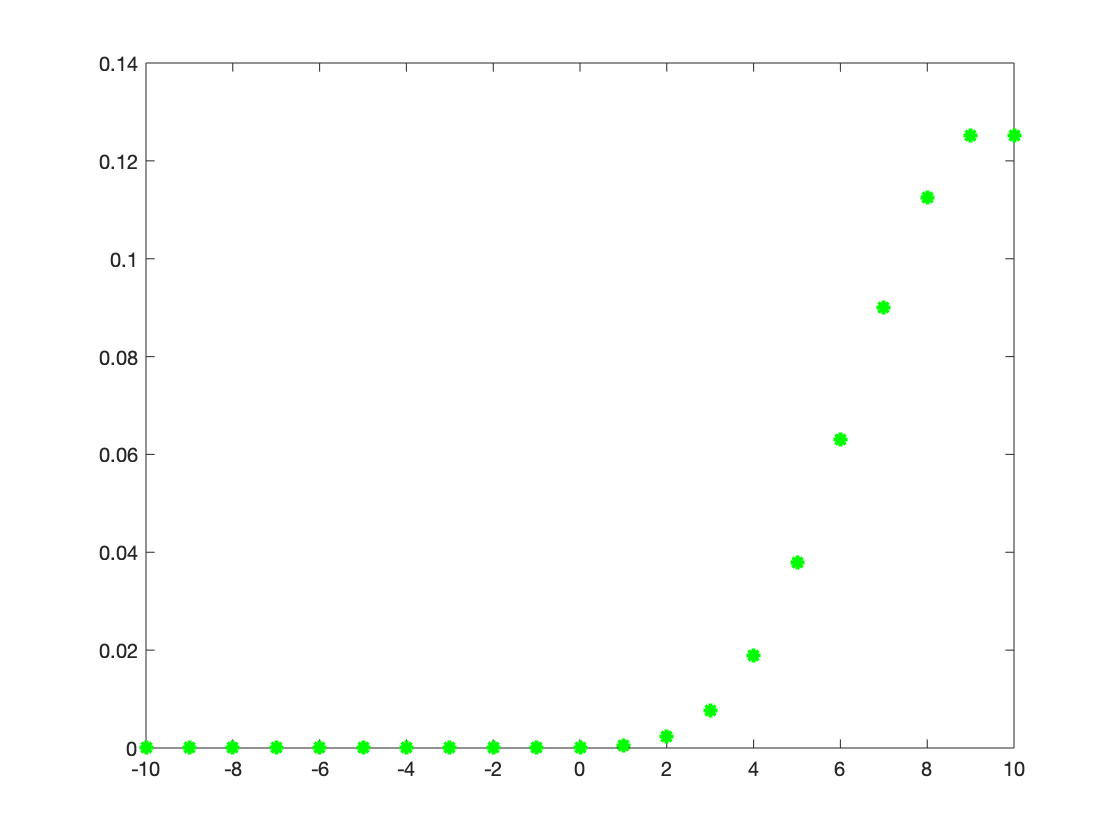


n = -10:10;
m = poisspdf(n,10);
plot(n,m,'g*',"Linewidth",2)

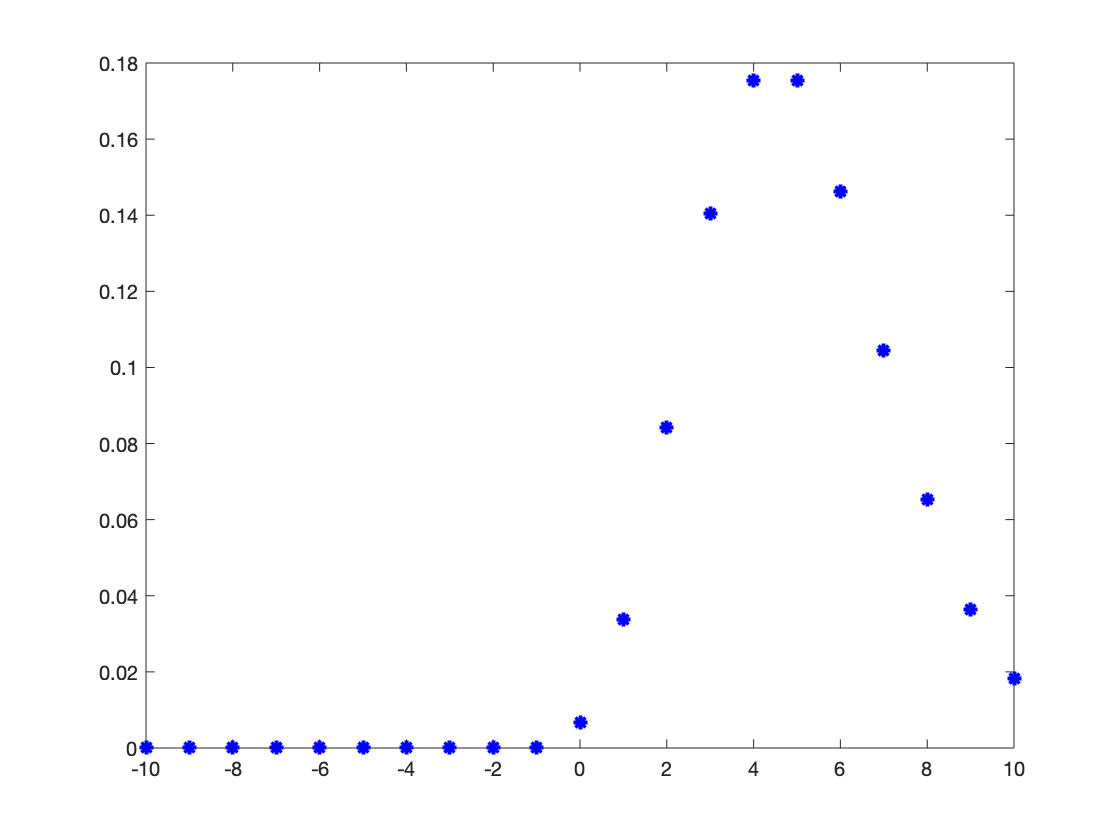


n = -10:10;
m = poisspdf(n,5);
plot(n,m,'b*',"LineWidth",2)

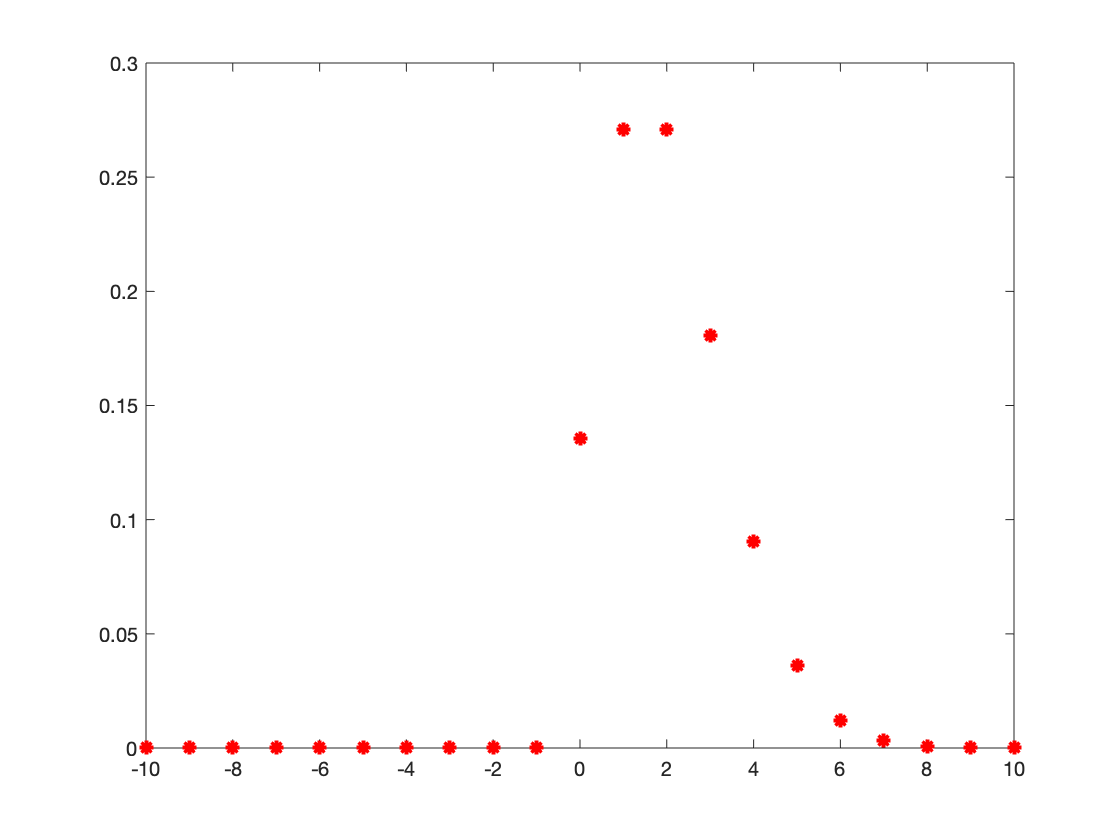


n = -10:10;
m = poisspdf(n,2);
plot(n,m,'r*',"LineWidth",2)

**Part C**

What is the probability that at pn=6 there will be not be a signal?

poisscdf(6,10,'upper')

ans = 0.8699

poisscdf(6,5,'upper')

ans = 0.2378

poisscdf(6,2,'upper')

ans = 0.0045

**Part D**

Because the Poisson distribution only takes integer valyes, we don't see values for events that would not be observed. An example is particle decay: there will never be 1.3 particles that are emitted and detected, so a distribution using integer values maks sense because it is not desired to see results that do not occur.

**Part E**

Values such as the mean are representing a mathematical concept, not a physical result or occurance. A concept such as the mean is helping in understanding the data by giving a value of what the average of the data is. For any additional data added, the mean will change accordingly because it is representing the data, but does not need to line up with the data's physical properties necessarily.